# Dynamic interpolation filter simulation

{Simulation 방법}

L, M, K, 

input_cycle

input_F0 등을 바꿔서 실험한다.

## Create input

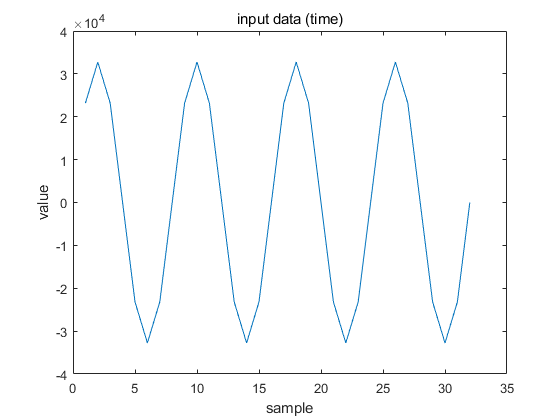


Fs=40e6; %[hz]

F0=5e6; %[hz]
input_cycle=4; %[cycle]
input_bitlength=16;
inputpulse=floor(sin([1:ceil(Fs/F0*input_cycle)]*2*pi*F0/Fs)*2^(input_bitlength-1));
plot(inputpulse);
xlabel('sample');
ylabel('value');
title('input data (time)')

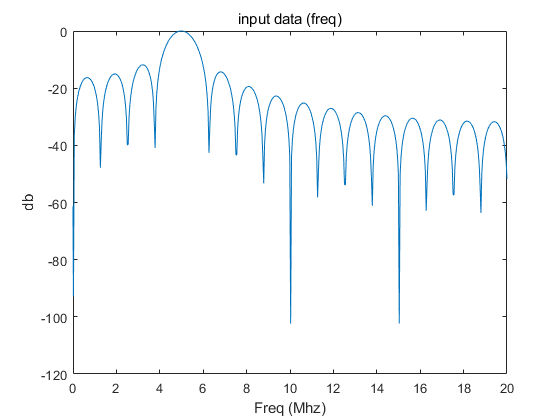

fft_plot(inputpulse,Fs,1000)
title('input data (freq)')

## Create Filter


K=16; % mac 개수
L=5;  % upsampling factor
M=3;  % downsampling factor
Coe.bitlength=18; % coefficient bit length


Coe.length=max(L,M)*K;
CutoffFreq=1/L;  % cutoff frequency with Normalized freq domain
disp('filter length');

filter length


disp(Coe.length);

    80



disp('Cutoff_Frequency');

Cutoff_Frequency


disp(cutoff);

    0.2000



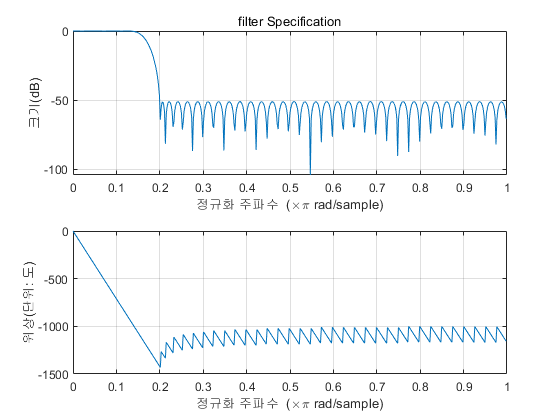

% filter making
Fst=cutoff;
Ap = 0.1;
Ast = 60;
Fp = Fst*2/3;
Hf=fdesign.lowpass('N,Fp,Fst',Coe.length-1,Fp,Fst);
Hd1 = design(Hf,'equiripple','systemobject',true);
Coe.values=Hd1.Numerator;
Coe.values=round(Coe.values*(2^(Coe.bitlength-1)));
figure;freqz(Coe.values/2^(Coe.bitlength-1));
title('filter Specification')

## Conventional filtering

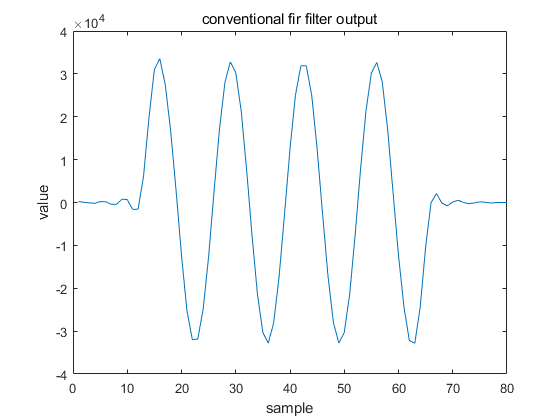

% conventional fir filter output
% with matlab
conv_fir_out=conv(upsample(inputpulse,L),Coe.values);
% bit truncation
conv_fir_out=round(conv_fir_out*L/2^(Coe.bitlength-1))';
conv_fir_out=downsample(conv_fir_out,M);
figure;plot(conv_fir_out);
xlabel('sample');ylabel('value');
title('conventional fir filter output');

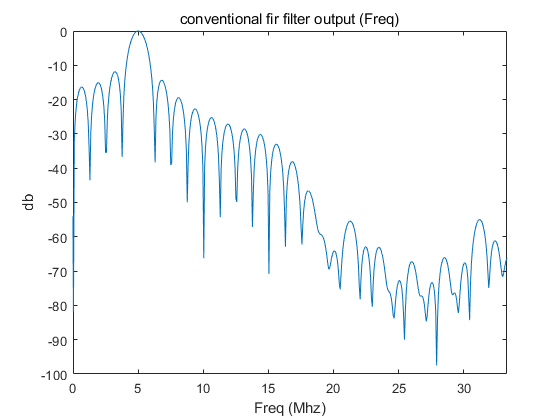


fft_plot(conv_fir_out,Fs*L/M,1000);
title('conventional fir filter output (Freq)');

## Proposed DIF method

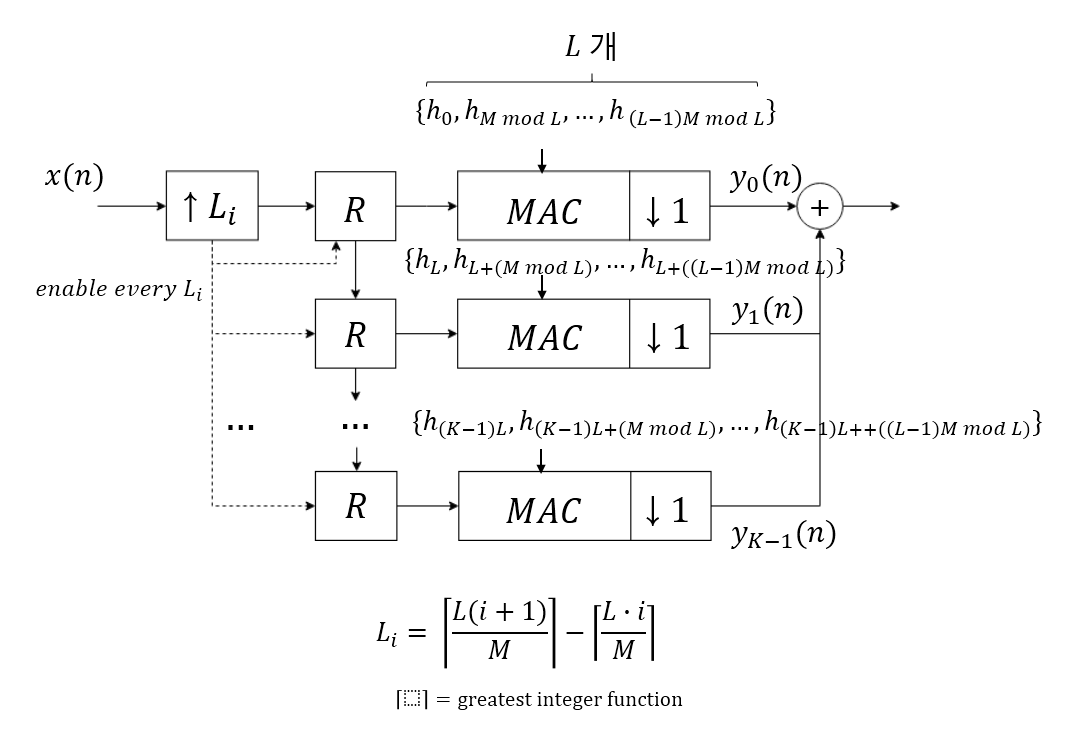


% Create MAC 

Li_array=[];
for i=0:M-1
    Li_array(i+1)=ceil(L*(i+1)/M)-ceil(L*i/M);
end
disp('Upsampling_array');

Upsampling_array


disp(Li_array)

     2     2     1




rearranged_coe=reshape(Coe.values,L,K)'

rearranged_coe =          257         149         126          51         -69
        -205        -315        -356        -294        -122
         131         406         617         685         554
         221        -255        -757       -1136       -1249
       -1005        -405         443        1336        2012
        2221        1798         727        -823       -2509
       -3865       -4400       -3711       -1591        1902
        6419       11367       16012       19617       21585
       21585       19617       16012       11367        6419
        1902       -1591       -3711       -4400       -3865


% K mac generate
MAC.coe=[];
for i=0:L-1
     MAC.coe=[MAC.coe rearranged_coe(:,mod(M*i,L)+1)];
end
disp('MAC_COEFFICIENT')

MAC_COEFFICIENT


disp('row mean K MAC')

row mean K MAC


disp('colomn mean coefficient of each MAC')

colomn mean coefficient of each MAC


disp(MAC.coe)

         257          51         149         -69         126
        -205        -294        -315        -122        -356
         131         685         406         554         617
         221       -1136        -255       -1249        -757
       -1005        1336        -405        2012         443
        2221        -823        1798       -2509         727
       -3865       -1591       -4400        1902       -3711
        6419       19617       11367       21585       16012
       21585       11367       19617        6419       16012
        1902       -4400       -1591       -3865       -3711
       -2509        1798        -823        2221         727
        2012        -405        1336       -1005         443
       -1249        -255       -1136         221        -757
         554         406         685         131         617
        -122        -315        -294        -205        -356
         -69         149          51         257         126



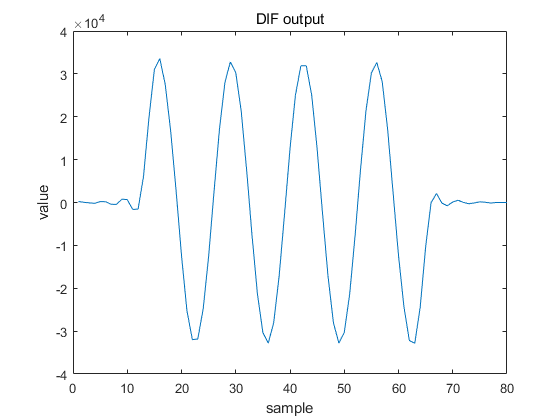



% output processing

length_proc=length(conv_fir_out);

Li_array_index=1;
input_index=1;
MAC.index=1;
upsampling_counter=0;
RegisterK=zeros(1,K);
DIF_output=[];

RegisterK=[inputpulse(input_index) RegisterK];
RegisterK=RegisterK(1:end-1);
for i=1:length_proc
    %% processing
    % register right shift
    MAC.out=RegisterK.*(MAC.coe(:,MAC.index)');
    DIF_output=[DIF_output round(sum(MAC.out)*L/2^(Coe.bitlength-1))']; % summation and bit_truncation
    
    MAC.index=mod(MAC.index,L)+1; %circular queue
    upsampling_counter=upsampling_counter+1;
    
    if upsampling_counter==Li_array(Li_array_index) 
        Li_array_index=mod(Li_array_index,M)+1;  %circular queue
        upsampling_counter=0;
        if(input_index>=length(inputpulse))
            %input data finished
            RegisterK=[0 RegisterK]; %zero insert
            RegisterK=RegisterK(1:end-1);
        else
            input_index=input_index+1;
            RegisterK=[inputpulse(input_index) RegisterK];
            RegisterK=RegisterK(1:end-1);
        end
    end
end


figure;plot(DIF_output);
xlabel('sample');ylabel('value');
title('DIF output');

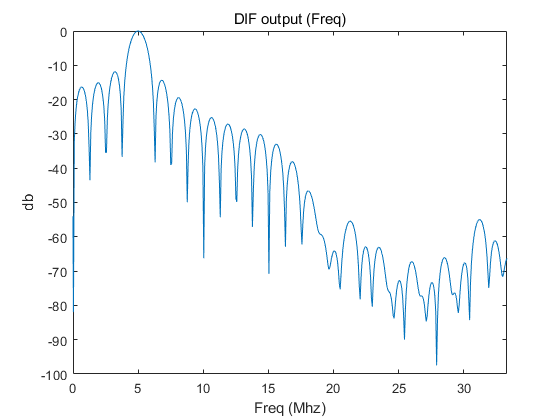


fft_plot(DIF_output,Fs*L/M,1000);
title('DIF output (Freq)');

## Output Difference

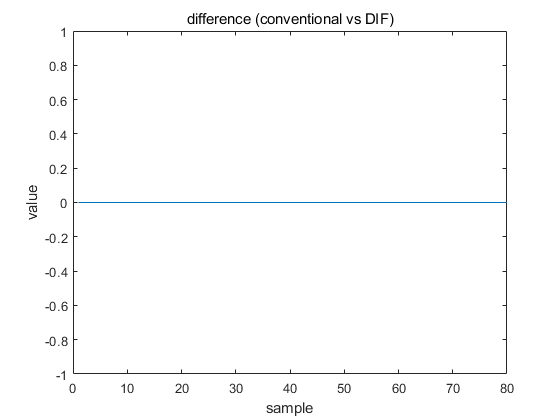

figure;plot(DIF_output(:)-conv_fir_out(:))
title('difference (conventional vs DIF)');
xlabel('sample');ylabel('value');